### **PBC Calculation**

clear variables
close all
clc

First of all we define the physical parameters of our system:

particleDensity = 1 % n = N\L

particleDensity = 1

cutoff = 30 % In ``Hartree''

cutoff = 30

V0 = 20 % In ``Hartree''

V0 = 20

W = 0.2 % Width of V(x)

W = 0.2000

And some computational parameter:

step = 100;     % Accuracy of numerical integrals
dx   = 1/step;
basisDIM = 100; % Basis dimension

Thermodynamic Limit:

$L\to\infty$, $N\to\infty$ such that $N/L = n$ is constant. 

So we need a cycle over L values:

Lmin = 14;  %
Lmax = 14;  % Only even values <=> Spinless electrons
Lstep = 4;  %

poles = zeros(step,step,step);
residues = zeros(step,step,step);

for L = Lmin:Lstep:Lmax 
    
    N = particleDensity*L;

Then we build the crystal hamiltonian computing matrix elements$\{\langle \psi^0_n | K + V(x) | \psi^0_m\rangle\}$:    

    % BZ k-points:
    
    N_b = nearest( basisDIM / N ) % Number of Bands
    E_k = zeros(N_b, N);
    c_k = zeros(N_b,N_b, N);
    
    E = [];
    c = [];
    dk = 2*pi/L;
    for k = 0:dk:2*pi
        ik = nearest(k/dk);
        % Hamiltonian Matrix for the u_k
        H_k = zeros(N_b,N_b);
        for n = (-N_b/2 + 1):(N_b/2)
            for m = (-N_b/2 + 1):(N_b/2)
                if n == m
                %% Kinetic (diagonal) part %%
                H_k(n + N_b/2,n + N_b/2) = 1/2*(q(ik,L)+G(n-1,1))^2;
                end    
                %% Periodic potential part 
                integrand = @(x) exp(1i*(G(n-1,1)-G(m-1,1))*x).*V(x,L,V0,W);
                braket = 1/L * integral(integrand,0,L);
                H_k(n + N_b/2,m + N_b/2) = H_k(n + N_b/2,m + N_b/2) + braket;
            end
        end

And look for eigen values and vectors:

        [c_k(:,:,ik + 1), E_k(:,ik + 1)] = eig(H_k,'vector');
        % Smart-Reshaffling in order to sort
        E = [E; E_k(:,ik + 1)];    % appended long array (col) of eigenvalues
        c = [c, c_k(:,:, ik + 1)]; % appended long array (row) of eigenvectors
    end

So now we compute the Fermi Energy of the perturbed system:

    % Energy Sorting:
    E_old = E;
    c_old = c;
    [E, n_old] = sort(E_old); 
    c = c_old(:,n_old);
    
    n = 1;
    N_el = 2; % Two electrons on the |k=0> state!
    while N_el < N
        n = n+2;
        N_el = N_el + 4; % Four electrons on each |k|!=0 level!
    end
    nF = n;
    EF = E(nF);

Resulting energy scheme is:

    if L == Lmax || L == Lmax - 3 || L == Lmax - 2 || L == Lmax - 1
        figure("Name",'PBC Energy Levels [REDUCED SCHEME]')
         for k = dk:dk:2*pi
             ik = nearest(k/dk);
             for n = 1:N_b
                 scatter(k-pi,E_old(n+N_b*ik),'markeredgecolor','black','markerfacecolor',[0, 0.4470, 0.7410]); hold on
             end
         end
         xlim([-pi,pi])
         ylim([5,50])
         yline(EF,'--','color', 'red','LineWidth', 1.5);
         ylabel('Atomic Units')
         title(sprintf('PBC Energy Levels for N = %d',N));
         set(gca, 'Box', 'on');
         set(gca,'xtick',[-pi,0,pi]);
         xticklabels({'-\pi','\Gamma','\pi'})
         %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%          figure("Name",'PBC Energy Levels [EXTENDED SCHEME]')
%          for n = 1:2:length(E)
%              k = 2*pi*(n-1)/L;
%              scatter(k,E(n),'markeredgecolor','black','markerfacecolor',[0, 0.4470, 0.7410]); hold on
%              scatter(-k,E(n),'markeredgecolor','black','markerfacecolor',[0, 0.4470, 0.7410]); hold on
%          end
%          ylim([5,50])
%          yline(EF,'--','color', 'red','LineWidth', 1.5);
%          ylabel('Atomic Units')
%          title(sprintf('PBC Energy Levels for N = %d',N));
%          set(gca, 'Box', 'on');
%          set(gca,'xtick',[-pi,0,pi]);
%          xticklabels({'-\pi','\Gamma','\pi'})
    end

## Geometrical Drude Weight

$D = 2v_\mathrm{F}$, with some care on what $v_\mathrm{F}$ is:

    if nF > 2
     % PBC Fermi velocity
        vF = (E(nF+2)-E(nF-2))/(2*dk);
     % PBC Geometrical Drude Weight
        deltaL = L-Lmin;
        Dw(deltaL/Lstep + 1) = 2*vF/pi;
    end

## Kubo Poles and Residues

Now we proced with linear response evaluation (Kubo Formulae)

- First we build up wavefunctions:

     x = linspace(0,L,step*L);
     psi = zeros(length(x),basisDIM);
     for n = 1:basisDIM
          psi_x = zeros(1,length(x));
          for m = 1:N_b
                psi_x = psi_x + psi0(x,m-1,L) * c(m,n);
          end
          psi(:,n) = psi_x;
     end
     
     if L == Lmax
         figure("Name",'Crystal Wavefunctions')
         plot(x,V(x,L,V0,W),'color',[0.7,0.7,0.7],'linewidth',1.5); hold on
         for n = 1:N
            plot(x,V0*real(psi(:,n)), 'linewidth', 1.5);
         end
     end

- Then we apply the velocity operator $\hat{v} = i  \frac{\mathrm{d}}{\mathrm{d}x}$:

     vpsi = zeros(length(x),basisDIM);
     dpsi_dx = zeros(1,length(x));
     for n = 1:basisDIM
         dpsi_dx(1:(length(x)-1)) = diff(psi(:,n))/dx;
         dpsi_dx(length(x)) = dpsi_dx(length(x)-1); % Border Trick
         vpsi(:,n) = 1i * dpsi_dx;
     end
     
%      figure("Name",'Derivative of Crystal Wavefunctions')
%      for n = 1:N
%         plot(x,imag(vpsi(:,n)), 'linewidth', 1.5); hold on
%      end

- So we can compute pole frequencies and residues:

     % Journey through all possible excited (many-body) states compatible with Pauli principle
     n = 1;
     w = zeros(basisDIM,basisDIM);
     res = zeros(basisDIM,basisDIM);
     while 1
         if n == nF
             break
         end
         m = nF;
         while 1
             dw = E(m)-E(n);
             if dw > cutoff
                 break
             end
             w(n,m) = dw; % Pole frequency
             braket_nm = conj(psi(:,n)).*vpsi(:,m);
             braket_mn = conj(vpsi(:,m)).*psi(:,n);
%              figure("Name",'Kubo Overlap')
%              plot(x,V(x, L,V0,W),'color',[0.5,0.5,0.5], 'linewidth', 2); hold on
%              plot(x,imag(braket_nm(:)), 'linewidth', 1.5);
%              plot(x,imag(braket_mn(:)), 'linewidth', 1.5);
             M1 = sum(braket_nm)*dx;
             M2 = sum(braket_mn)*dx;
             %if abs(M1) < 0.01 || abs(M2) < 0.01
             %    res(n,m) = 0;
             %else
                  res(n,m) = 4*M1*M2/(dw*L);              
             %end
              m = m+1;
         end
         n = n+1;
     end
     nMax = n;
     mMax = m;
     
     % Smart reshaffling:
     deltaL = L-Lmin;
     nPoles = zeros(1,mMax-1);
     nResidues = zeros(1,mMax-1);
     for n = 1:nF
         for m_n = 1:(mMax-n)
             m = n + m_n; % i.e. m-n = m_n ;)
             nPoles(m_n) = w(n,m);
             nResidues(m_n) = res(n,m);
         end
         poles(n, deltaL/Lstep+1, 1:length(nPoles)) = nPoles;
         residues(n, deltaL/Lstep+1, 1:length(nResidues)) = nResidues;
     end

N_b = 7

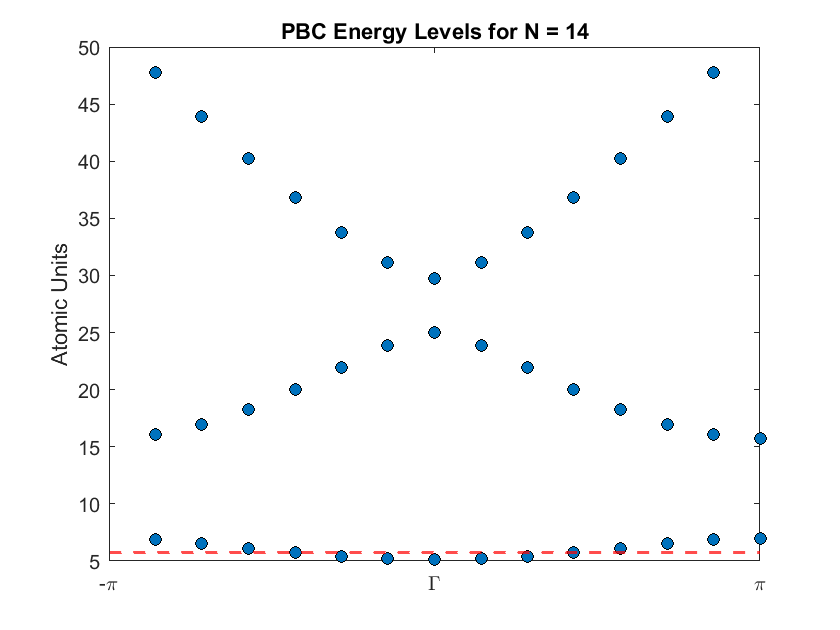

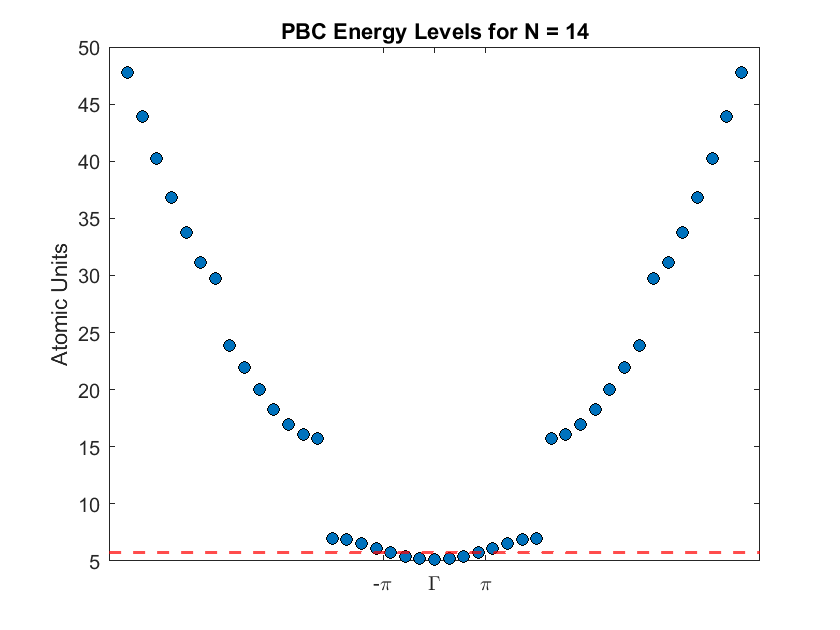

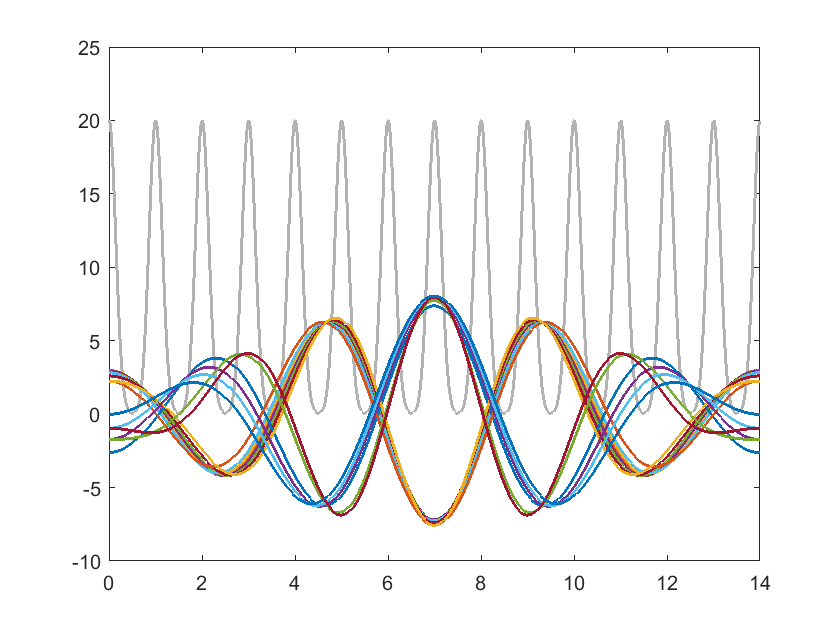

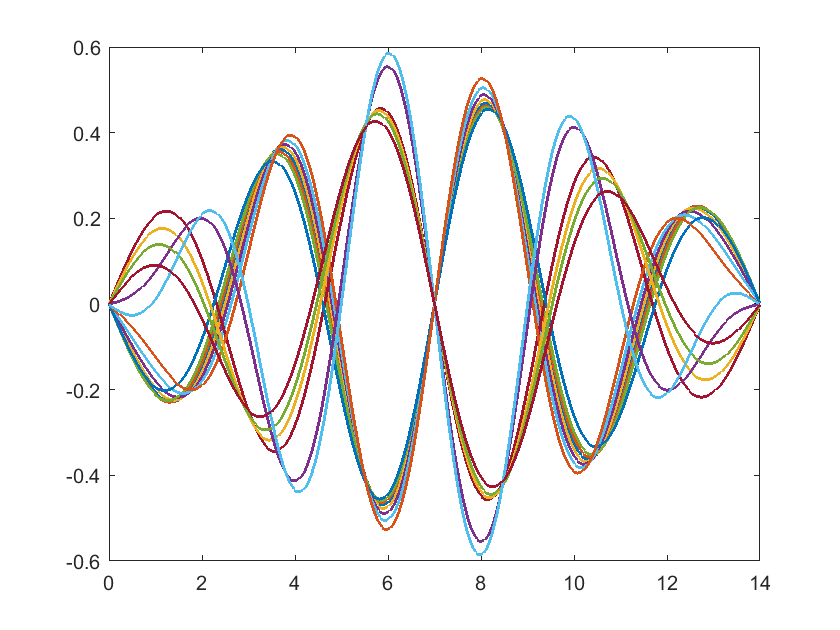

end

Drude Weight and F-sum:

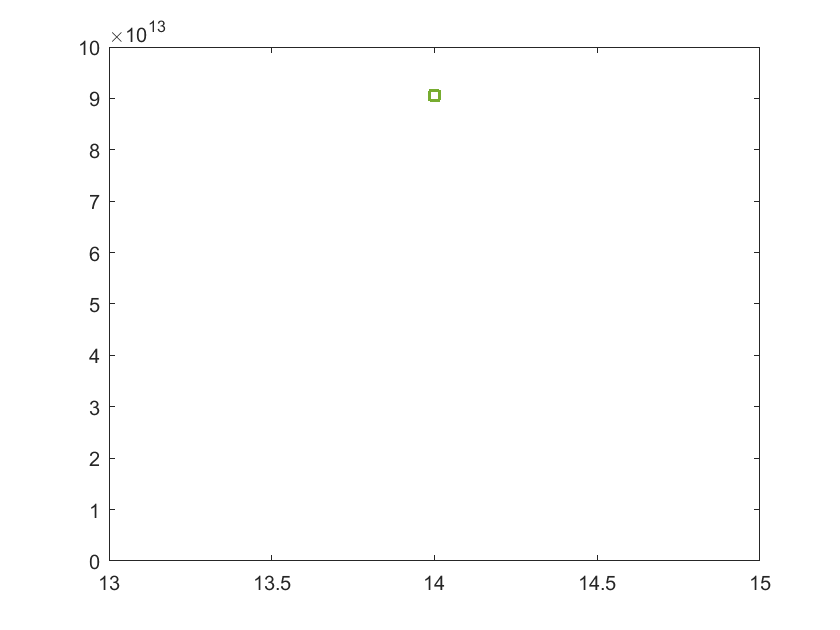

% Determing Treshold
spacing = zeros(1,basisDIM-1);
for n = 1:mMax
 spacing(n) = E(n+1) - E(n);
end
[gap,nV] = max(spacing);
nC = nV + 1;
Ev = E(nV);
Ec = E(nC);
w_th = Ec - E(1);

% F(R)-sum
Ls = Lmin:Lstep:Lmax;
for L = Ls
    deltaL = L-Lmin;
    L_freq = poles(:,deltaL/Lstep+1,:);
    L_res = residues(:,deltaL/Lstep+1,:);
    F_res = L_res(L_freq > 0);
    FSum(deltaL/Lstep+1) = sum(F_res);
end
red = [1, 0, 0];
blood = [0.6350, 0.0780, 0.1840];
green = [0.4660, 0.6740, 0.1880];
orange = [0.9290, 0.6940, 0.1250];
figure("Name",'F-Sum Analysis')
plot(Ls,FSum,'s-','color',green,'LineWidth',1.5);hold on
plot(Ls,Dw,'-','color',blood,'LineWidth',1.5);

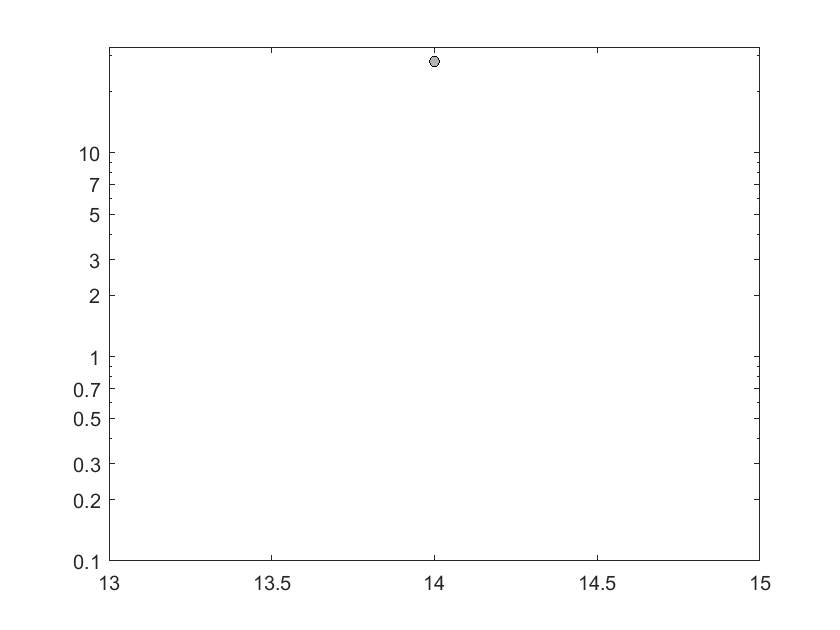


figure("Name",'Pole-Frequency Analysis')
Ls = Lmin:Lstep:Lmax;
for n = 1:nMax
    CM = prism(mMax-n);
    for m_n = 1:(mMax-n)
        freqs = poles(n,:,m_n);
        Rfreqs = freqs(freqs > 0);
        RLs = Ls(freqs > 0);
        plot(RLs,Rfreqs,'o','MarkerEdgeColor', 'black','MarkerFaceColor',[0.7,0.7,0.7],'MarkerSize', 5);
        yticks([0.1 0.2 0.3 0.5 0.7 1 2 3 5 7 10])
        set(gca, 'Ylim', [0.1,cutoff*1.1]);
        set(gca, 'YScale', 'log');
        set(gca, 'Box', 'on');
    end
end

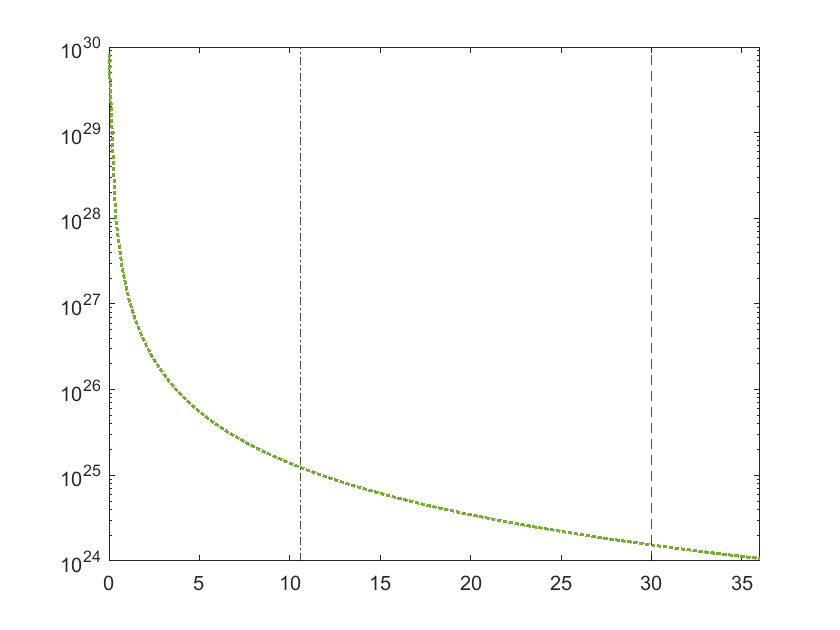


figure("Name", 'PBC Conductivity')
z = linspace(0,1.2*cutoff,step);
Gz = zeros(1,length(z));
eta = 0.1*EF/Lmax;
freqs = poles(poles~=0);
resds = residues(poles~=0);
for n = 1:length(freqs)
        dw = freqs(n);
        Res = resds(n);
        Gz = Gz + 1i*Res.*(1./(dw.*(z-dw+1i*eta))+1./(dw.*(z+dw+1i*eta)));
end
plot(z,real(Gz),':','LineWidth', 1.5, 'color', green); hold on
xline(w_th,'-.','color', 'black');
xline(cutoff,'--','color', 'black');
set(gca,'Xlim',[0,1.2*cutoff]);
set(gca,'Yscale','log')


figure("Name",'Pole-Frequency Spaghetti')
Ls = Lmin:Lstep:Lmax;
Dfreqs = [];
DLs = [];
Rfreqs = [];
RLs = [];
CM = prism(mMax-n);
for m_n = 1:(mMax-n)
    for  n = 1:nMax
        freqs = poles(n,:,m_n);
        Dfreqs = [Dfreqs,freqs(freqs < w_th & freqs > 0)];
        DLs = [DLs, Ls(freqs < w_th & freqs > 0)];
        Rfreqs = [Rfreqs, freqs(freqs > w_th & freqs > 0)];
        RLs = [RLs,Ls(freqs > w_th & freqs > 0)];
        plot(RLs,Rfreqs,'-','MarkerEdgeColor', 'black','MarkerFaceColor',[0.7,0.7,0.7],'MarkerSize', 5);
    end
        plot(DLs,Dfreqs,'-','MarkerEdgeColor', 'black','MarkerFaceColor',CM(m_n,:), 'MarkerSize', 5); hold on
        yline(w_th,'--'); 
        yticks([0.1 0.2 0.3 0.5 0.7 1 2 3 5 7 10])
        set(gca, 'Ylim', [0.1,cutoff*1.1]);
        set(gca, 'YScale', 'log');
        set(gca, 'Box', 'on');
end


Reciprocal Space wavevectors: $G = \frac{2\pi n}{a}$ 

function K = G(n,a)
         K = (2*pi*n)/a;
end

Brillouin Zone wavevectors: $k = \frac{2\pi n}{L}$

function k = q(m,L)
         k = (2*pi*m)/L;
end

Imperturbed EXTENDED SCHEME eigenfunctions $\psi^0_n(x)$: 

function psi0_n = psi0(x,m,L)
         A = sqrt(1/L); % Normalization
         psi0_n = A*exp(1i*q(m,L).*x);
end

Periodic potential $V(x)$ as a sum of Gaussians:

function U = V(x,L,V0,W)
         
         U = 0;
         for x_i = 0:L+1 
             U = U + V0*exp(-(x-x_i).^2 / W^2);                        
         end
end